# Lab 2: Exploring use of MATLAB to display and modify images

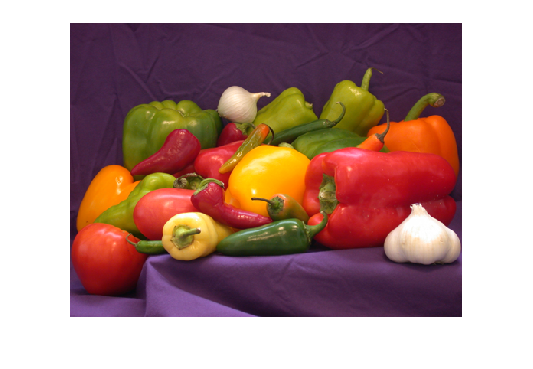

% Loading and displaying the image 
im = imread('peppers.png');
imshow(im)


% getting dimensions of the image 
im_size = size(im)

im_size =    384   512     3


fprintf("Image Dimensions: %.f x %.f with %.f colors", im_size)

Image Dimensions: 384 x 512 with 3 colors

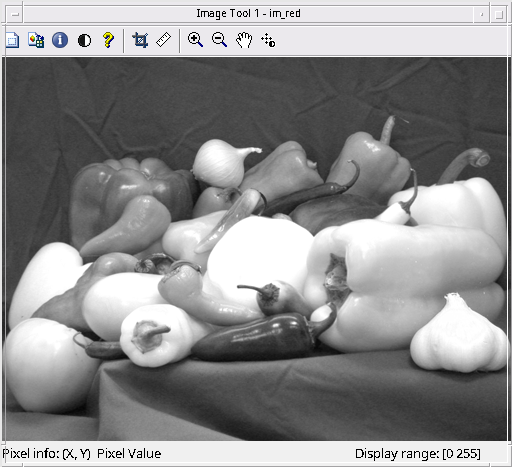


% using imtool to display just the red plane 
im_red = im(:,:,1);
im_blue = im(:,:,2);
im_green = im(:,:,3);

imtool(im_red)

imtool(im_green)
imtool(im_blue)

%% Applying gray scale algorithm to the image 
% and gathering statistics 
im_gray = rgb2gray(im)
im_gray_size = size(im_gray)
imshow(im_gray)

fprintf("The Grayscale Image has dimensions %.f x %.f with no rgb value", im_gray_size)

%% Getting Gray Scale Statistics 
im_gray_min = min(min(im_gray))
im_gray_max = max(max(im_gray))

% Calculating Average Pixel Intensity 
im_gray_len = im_gray_size(1)
im_gray_width = im_gray_size(2)

im_gray_area = im_gray_len * im_gray_width
im_gray_avg = sum(sum(im_gray)) / im_gray_area

% Histogram Plot 
imhist(im)
title('Gray Scale Intensity')
xlabel("Pixel Vlaue (Intensity)")
ylabel("Quantity")

% Displaying the top half of the intensity image 
imtool(im_gray(1:im_gray_size/2,:))


% Displaying the right half of the intensity image 
imtool(im_gray(:,im_gray_size/2:im_gray_size))

% Converting to a binary image 
im_gray_binary = imbinarize(im_gray);
imshow(im_gray_binary) % values are either 0 or 1

% reducing image size
im_reduced_1 = imresize(im,.5);
imshow(im_reduced_1)

im_reduced_2 = imresize(im, [200,200]);
imshow(im_reduced_2)


## Personal Image 1

% Loading and displaying the image 
im = imread('/home/aaron/Projects/matlab/lab_2/bike.jpg');
imshow(im)

imwrite(im, 'im_bike','jpg')

% getting dimensions of the image 
im_size = size(im)
fprintf("Image Dimensions: %.f x %.f with %.f colors", im_size)

% using imtool to display just the red plane 
im_red = im(:,:,1);
im_blue = im(:,:,2);
im_green = im(:,:,3);

imshow(im_red)
imshow(im_green)
imshow(im_blue)

imwrite(im_red, 'im__bike_red.jpg','jpg')
imwrite(im_green, 'im__bike_green.jpg','jpg')
imwrite(im_blue, 'im_bike_blue.jpg','jpg')


%% Applying gray scale algorithm to the image 
% and gathering statistics 
im_gray = rgb2gray(im);
im_gray_size = size(im_gray)

imshow(im_gray)
imwrite(im_gray, 'im_bike_gray.jpg','jpg')

fprintf("The Grayscale Image has dimensions %.f x %.f with no rgb value", im_gray_size)

%% Getting Gray Scale Statistics 
im_gray_min = min(min(im_gray))
im_gray_max = max(max(im_gray))

% Calculating Average Pixel Intensity 
im_gray_len = im_gray_size(1)
im_gray_width = im_gray_size(2)

im_gray_area = im_gray_len * im_gray_width
im_gray_avg = sum(sum(im_gray)) / im_gray_area

% Histogram Plot 
imhist(im)
title('Gray Scale Intensity')
xlabel("Pixel Vlaue (Intensity)")
ylabel("Quantity")

% Displaying the top half of the intensity image 
imwrite(im_gray(1:im_gray_size(1)/2,:), 'im_bike_top.jpg','jpg')


% Displaying the right half of the intensity image 
imwrite(im_gray(:, im_gray_size(2)/2:im_gray_size(2)), 'im_big_right.jpg','jpg')


% Converting to a binary image 
im_gray_binary = imbinarize(im_gray);
imwrite(im_gray_binary, 'im_gray_binary', 'jpg') % values are either 0 or 1

% reducing image size
im_reduced_1 = imresize(im,.5);
imwrite(im_reduced_1, 'im_reduced_1.jpg','jpg')

im_reduced_2 = imresize(im, [200,200]);
imwrite(im_reduced_2, 'im_reduced_2.jpg','jpg')




## Personal Image 2:

% Loading and displaying the image 
im_tropic = imread('/home/aaron/Projects/matlab/lab_2/tropic.JPG');
imshow(im_tropic)

imwrite(im_tropic, 'im_tropic','jpg')

% getting dimensions of the image 
im_size = size(im_tropic)
fprintf("Image Dimensions: %.f x %.f with %.f colors", im_size)

% using imtool to display just the red plane 
im_red = im_tropic(:,:,1);
im_blue = im_tropic(:,:,2);
im_green = im_tropic(:,:,3);

imshow(im_red)
imshow(im_green)
imshow(im_blue)


imwrite(im_red, 'im_tropic_red','jpg')
imwrite(im_green, 'im_tropic_green','jpg')
imwrite(im_blue, 'im_tropic_blue','jpg')

%% Applying gray scale algorithm to the image 
% and gathering statistics 
im_gray = rgb2gray(im_tropic)
im_gray_size = size(im_gray)

imshow(im_gray)
imwrite(im_gray, 'im_tropic_gray','jpg')
fprintf("The Grayscale Image has dimensions %.f x %.f with no rgb value", im_gray_size)

%% Getting Gray Scale Statistics 
im_gray_min = min(min(im_gray))
im_gray_max = max(max(im_gray))

% Calculating Average Pixel Intensity 
im_gray_len = im_gray_size(1)
im_gray_width = im_gray_size(2)

im_gray_area = im_gray_len * im_gray_width
im_gray_avg = sum(sum(im_gray)) / im_gray_area

% Histogram Plot 
imhist(im_tropic)
title('Gray Scale Intensity')
xlabel("Pixel Vlaue (Intensity)")
ylabel("Quantity")

% Displaying the top half of the intensity image 
imwrite(im_gray(1:im_gray_size(1)/2,:), 'im_tropic_top.jpg','jpg')

% Displaying the right half of the intensity image 
imwrite(im_gray(1:im_gray_size(1)/2,:), 'im_tropic_right.jpg','jpg')
% Converting to a binary image 
im_gray_binary = imbinarize(im_gray);
imwrite(im_gray_binary,'im_tropic_binary.jpg','jpg') % values are either 0 or 1

% reducing image size
im_reduced_1 = imresize(im,.5);
imwrite(im_reduced_1, 'im_reduced_tropic_1.jpg','jpg')

im_reduced_2 = imresize(im, [200,200]);
imwrite(im_reduced_2, 'im_reduced_tropic_2.jpg','jpg')
